D=[ 0 0 -1 1;
    1 -1 -1 -1;
    0 1 -1 -1;
    1 1 1 1];


ADJ=[ 0 1 1 1;
      1 0 1 1;
      1 1 0 1;
      1 1 1 0];

## Projection

center of projection at (a,b,c)

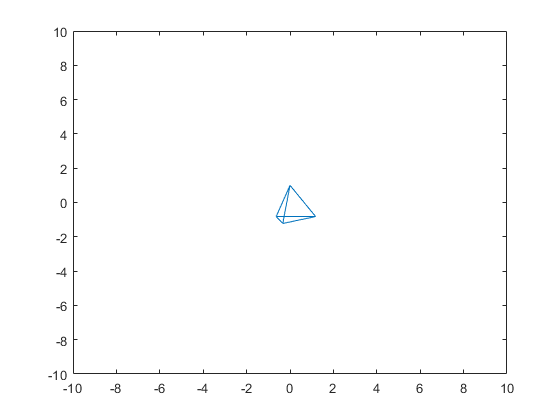

b=3;c=1;d=10;
  
P=[1 0 -b/d 0;
   0 1 -c/d 0;
   0 0   0  0;
   0 0 -1/d 1];
 
%calculate projected coordinates
D2=P*D;
D2(1,:)=D2(1,:)./D2(4,:);
D2(2,:)=D2(2,:)./D2(4,:);
xy=D2(1:2,:)';
gplot(ADJ,xy)
axis([-10 10 -10 10]);

%pause


## Rotation

Roter med 10 grader omkring y-aksen

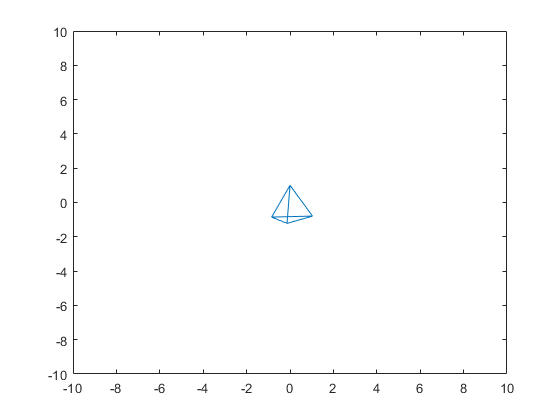

yrot=10*pi/180;   % angle in radians
Ry=[cos(yrot)  0 sin(yrot)  0;
    0          1      0     0;
    -sin(yrot) 0 cos(yrot)  0;
    0          0     0      1];
    
D2=P*Ry*D;
D2(1,:)=D2(1,:)./D2(4,:);
D2(2,:)=D2(2,:)./D2(4,:);
xy=D2(1:2,:)';
gplot(ADJ,xy)
axis([-10 10 -10 10]);